clc,clear,close all

syms x_1 x_2 x_3

f = [10*x_1-2*x_3+cos(x_2*x_3)+3*sin(x_1)
    2*x_2^2+10*x_2+2*x_1-x_3+2
    2*x_2+8*x_3+exp(-x_1-x_3)-1]

$$f = \left(\begin{array}{c} 10\,x_{1}-2\,x_{3}+\cos\left(x_{2}\,x_{3}\right)+3\,\sin\left(x_{1}\right)\\ 2\,{x_{2}}^{2}+10\,x_{2}+2\,x_{1}-x_{3}+2\\ 2\,x_{2}+8\,x_{3}+{\mathrm{e}}^{-x_{1}-x_{3}}-1 \end{array}\right)$$


x0 = [1.25
    1.11
    0];
x = [x_1
    x_2
    x_3];

vpasolve(f==zeros(3,1))

ans = 包含以下字段的 struct :
    x_1: -0.070189567013566748062832332170141
    x_2: -0.18869990383830753664815862942527
    x_3: 0.043837135006964160196974007413881


误差-迭代次数图为


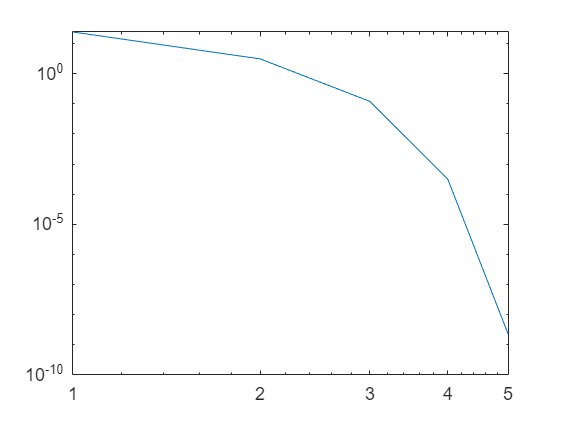

迭代次数为
     5

误差为
   2.2129e-09

初值设置为
    1.2500
    1.1100
         0

所需时间为
0.35693s


eqa_solve =    -0.0702
   -0.1887
    0.0438



delta0 = 1e-6;


eqa_solve = Newton_solve(f,x,x0,delta0)


disp('牛顿法得到方程的解为')

牛顿法得到方程的解为


disp(eqa_solve)

   -0.0702
   -0.1887
    0.0438




double(subs(subs(subs(f,x_1,eqa_solve(1)),x_2,eqa_solve(2)),x_3,eqa_solve(3)))

ans = 1.0e-16 *

   -0.6186
   -0.0794
   -0.1207
